Simulando: a = 0.50 | β = 15.0


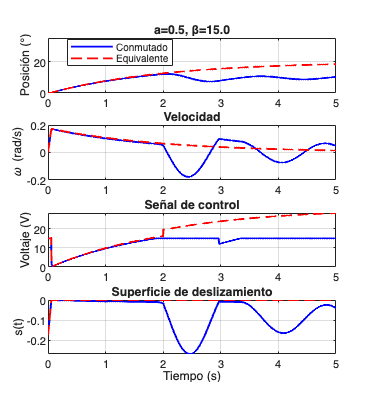

Simulando: a = 1.00 | β = 20.0


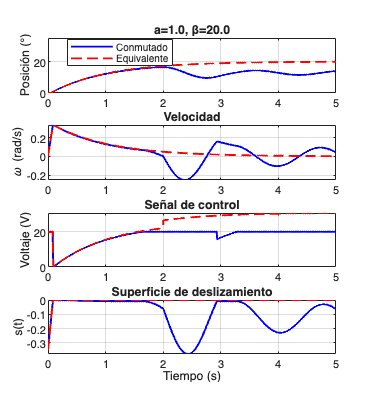

Simulando: a = 2.00 | β = 28.0


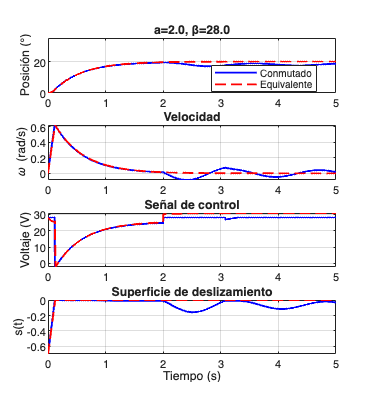

Simulando: a = 5.00 | β = 35.0


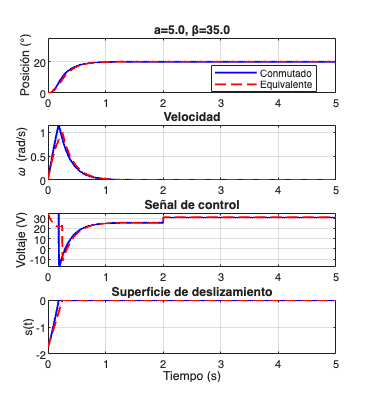

Simulando: a = 10.00 | β = 60.0


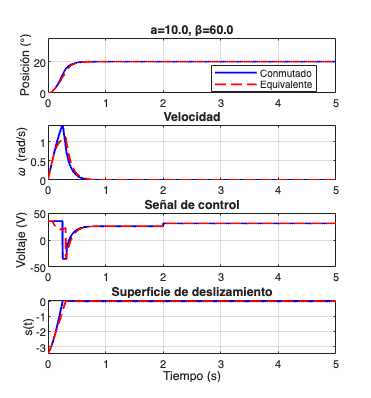

Simulando: a = 15.00 | β = 90.0


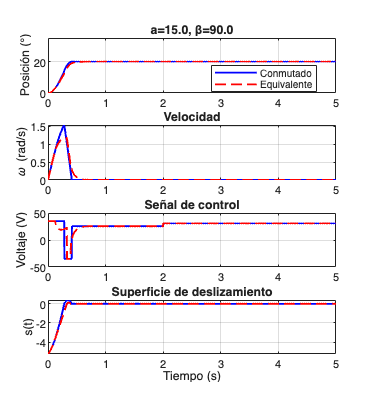


R  = 8; 
J  = 9.85e-3; 
B  = 2.52e-3; 
Km = 1.57e-2; 
Ke = Km; 
M0 = 0.3; 
r  = 0.05; 
g  = 9.81;

a_vals    = [0.5 1 2 5 10 15];
beta_vals = [15 20 28 35 60 90];
phi       = 0.01;
xr        = deg2rad(20);
tspan     = [0 5];
x0        = [0; 0];
Vmax      = 35;
colores   = lines(length(a_vals));


results_switch = repmat(struct('t',[],'x',[],'u',[],'s',[],'a',[],'beta',[]), length(a_vals),1);
results_equiv  = repmat(struct('t',[],'x',[],'u',[],'s',[],'a',[],'beta',[]), length(a_vals),1);

for k = 1:length(a_vals)
    a = a_vals(k);
    beta = beta_vals(k);
    fprintf('Simulando: a = %.2f | β = %.1f\n', a, beta);

    [t1, x1, u1, s1] = simSMC(R,J,B,Km,Ke,M0,r,g,a,beta,phi,xr,tspan,x0,false,true,Vmax);
    [t2, x2, u2, s2] = simSMC(R,J,B,Km,Ke,M0,r,g,a,beta,phi,xr,tspan,x0,true,true,Vmax);

    results_switch(k) = struct('t',t1,'x',x1,'u',u1,'s',s1,'a',a,'beta',beta);
    results_equiv(k)  = struct('t',t2,'x',x2,'u',u2,'s',s2,'a',a,'beta',beta);

    figure('Name',sprintf('SMC - a=%.1f, β=%.1f',a,beta),'Position',[100 100 700 750]);
    subplot(4,1,1)
    plot(t1,rad2deg(x1(:,1)),'b',t2,rad2deg(x2(:,1)),'r--','LineWidth',1.4);
    ylabel('Posición (°)'); title(sprintf('a=%.1f, β=%.1f',a,beta));
    legend('Conmutado','Equivalente','Location','Best'); grid on; ylim([0 35]);

    subplot(4,1,2)
    plot(t1,x1(:,2),'b',t2,x2(:,2),'r--','LineWidth',1.4);
    ylabel('\omega (rad/s)'); title('Velocidad'); grid on;

    subplot(4,1,3)
    plot(t1,u1,'b',t2,u2,'r--','LineWidth',1.4);
    ylabel('Voltaje (V)'); title('Señal de control'); grid on;

    subplot(4,1,4)
    plot(t1,s1,'b',t2,s2,'r--','LineWidth',1.4);
    ylabel('s(t)'); xlabel('Tiempo (s)'); title('Superficie de deslizamiento'); grid on;
end

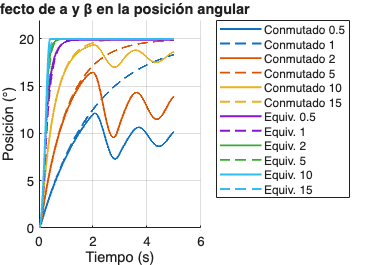


figure('Name','Comparación Global - Posición','Position',[100 100 700 500]);
hold on
for k=1:length(a_vals)
    plot(results_switch(k).t, rad2deg(results_switch(k).x(:,1)),'-','Color',colores(k,:),'LineWidth',1.4);
    plot(results_equiv(k).t, rad2deg(results_equiv(k).x(:,1)),'--','Color',colores(k,:),'LineWidth',1.4);
end
xlabel('Tiempo (s)'); ylabel('Posición (°)');
title('Efecto de a y β en la posición angular');
legend({'Conmutado 0.5','Conmutado 1','Conmutado 2','Conmutado 5','Conmutado 10','Conmutado 15',...
        'Equiv. 0.5','Equiv. 1','Equiv. 2','Equiv. 5','Equiv. 10','Equiv. 15'},'Location','BestOutside');
grid on; ylim([0 22]);

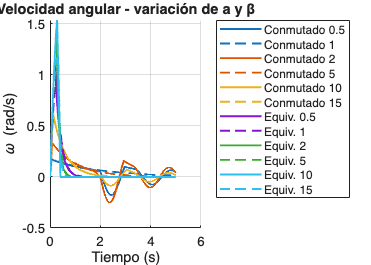


figure('Name','Comparación Global - Velocidad','Position',[850 100 700 500]);
hold on
for k=1:length(a_vals)
    plot(results_switch(k).t, results_switch(k).x(:,2),'-','Color',colores(k,:),'LineWidth',1.4);
    plot(results_equiv(k).t, results_equiv(k).x(:,2),'--','Color',colores(k,:),'LineWidth',1.4);
end
xlabel('Tiempo (s)'); ylabel('\omega (rad/s)');
title('Velocidad angular - variación de a y β');
legend({'Conmutado 0.5','Conmutado 1','Conmutado 2','Conmutado 5','Conmutado 10','Conmutado 15',...
        'Equiv. 0.5','Equiv. 1','Equiv. 2','Equiv. 5','Equiv. 10','Equiv. 15'},'Location','BestOutside');
grid on;

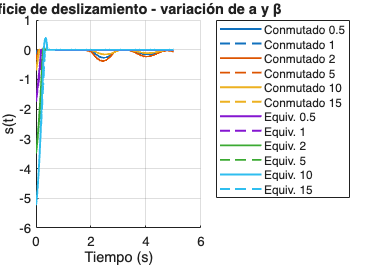


figure('Name','Comparación Global - s(t)','Position',[500 650 700 500]);
hold on
for k=1:length(a_vals)
    plot(results_switch(k).t, results_switch(k).s,'-','Color',colores(k,:),'LineWidth',1.4);
    plot(results_equiv(k).t, results_equiv(k).s,'--','Color',colores(k,:),'LineWidth',1.4);
end
xlabel('Tiempo (s)'); ylabel('s(t)');
title('Superficie de deslizamiento - variación de a y β');
legend({'Conmutado 0.5','Conmutado 1','Conmutado 2','Conmutado 5','Conmutado 10','Conmutado 15',...
        'Equiv. 0.5','Equiv. 1','Equiv. 2','Equiv. 5','Equiv. 10','Equiv. 15'},'Location','BestOutside');
grid on;


function [t,x,u_hist,s_hist]=simSMC(R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,tspan,x0,eq_flag,perturb,Vmax)
    opts=odeset('RelTol',1e-6,'AbsTol',1e-8);
    sol=ode45(@(t,x) odeSMC(t,x,R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,eq_flag,perturb,Vmax),tspan,x0,opts);
    t=linspace(tspan(1),tspan(2),1000);
    x=deval(sol,t)'; u_hist=zeros(size(t)); s_hist=zeros(size(t));
    for i=1:length(t)
        [u_hist(i),s_hist(i)]=controlSMC(x(i,:),R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,eq_flag,perturb,t(i),Vmax);
    end
end

function dx=odeSMC(t,x,R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,eq_flag,perturb,Vmax)
    [u,~]=controlSMC(x,R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,eq_flag,perturb,t,Vmax);
    if perturb && t>=2, M=M*1.2; end
    tau_load=M*g*r*sin(x(1));
    c1=(B+Km*Ke/R)/J; gg=Km/(J*R);
    dx=[x(2); -c1*x(2)+gg*u-tau_load/J];
end

function [u,s]=controlSMC(x,R,J,B,Km,Ke,M,r,g,a,beta,phi,xr,eq_flag,perturb,t,Vmax)
    e=x(1)-xr; s=a*e+x(2); sat=max(-1,min(1,s/phi));
    if perturb && t>=2, M=M*1.2; end
    c1=(B+Km*Ke/R)/J; gg=Km/(J*R);
    f=-c1*x(2)-(M*g*r*sin(x(1)))/J;
    if eq_flag
        ueq=-(a*x(2)+f)/gg; u=ueq-beta*sat;
    else
        u=-beta*sat;
    end
    u=max(-Vmax,min(Vmax,u));
end
